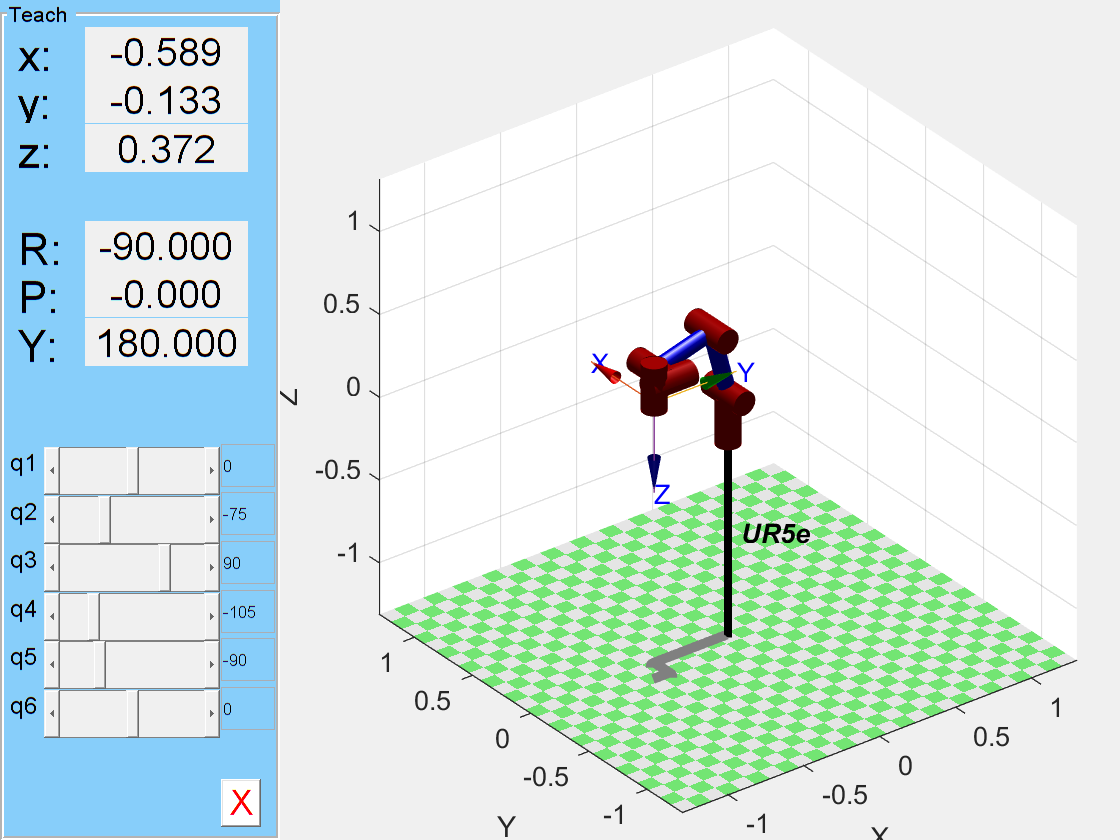

jointConfiguration = deg2rad([0.00, -75.00, 90.00, -105.00, -90.00, 0.00]);
L(1) = Link([0, 0.1625, 0,  pi/2]); % Link 1
L(2) = Link([0, 0, -0.425,  0]); % Link 2
L(3) = Link([0,  0, -0.3922, 0]); % Link 3
L(4) = Link([0, 0.1333, 0,  pi/2]); % Link 4
L(5) = Link([0, 0.0997, 0,  -pi/2]); % Link 5
L(6) = Link([0, 0.0996, 0,  0]); % Link 6
% Creating the robot
robot = SerialLink(L, 'name', 'UR5e');
fkine(robot, jointConfiguration)
robot.teach(jointConfiguration)


fkine(robot, jointConfiguration)

 

ans = 
         0         1         0   -0.5885
         1         0         0   -0.1333
         0         0        -1    0.3719
         0         0         0         1
